# **BÀI THI GIỮA KỲ**

- `Họ và tên Học viên: Đỗ Thế Sang `

- `Mã số Học viên: `**1001240027**

- `Ngày tháng năm sinh: 2002/09/20`

**Đề bài:** Thiết kế mạng thần kinh tích chập (CNN) để phân loại Biển báo tốc độ giao thông dựa trên bộ dữ liệu được giảng viên cung cấp.

- Nộp bài: gửi đến email: bao.dq@vlu.edu.vn.

- Tiêu đề mail: [BÀI GIỮA KỲ LỚP: HỌC MÁY NÂNG CAO]

- Nộp bằng email của Học viên.

- Định dạng file: Nộp file .mlx với kết quả hiển thị kèm theo.

- Quy cách dặt tên file: HoTenMSSV.mlx (Ví dụ: NguyeVanA6789.mlx)

- Thang điểm như cung cấp bên dưới, 1 điểm trình bày, và 3 điểm đánh giá độ chính xác trên tập TEST, tổng là 10 điểm.

- Các bài làm giống nhau là 0 điểm.

- Hạn nộp: 10/04/2025.

# Tạo và Huấn luyện Mạng Thần Kinh Tích Chập để Phân Loại Biển Báo Giao Thông

Bạn sẽ:

- Chuẩn bị bộ dữ liệu biển báo giao thông để huấn luyện.

- Tạo Mạng Thần Kinh Tích Chập (CNN).

- Huấn luyện mô hình để phân loại biển báo giao thông.

- Đánh giá mô hình đã huấn luyện trên dữ liệu kiểm tra (test).

## Chuẩn bị Dữ liệu để Huấn Luyện `[1 điểm]`

Trong thư mục "Traffic Signs", dữ liệu đã được phân chia sẵn thành hai thư mục: **Train** (Huấn luyện) và **Test** (Kiểm tra).

Tạo một datastore ảnh từ tập dữ liệu huấn luyện, đặt tên là `imdsSigns`:

trainFolder = "/MATLAB Drive/German_Traffic_Sign/Train"

trainFolder = "/MATLAB Drive/German_Traffic_Sign/Train"

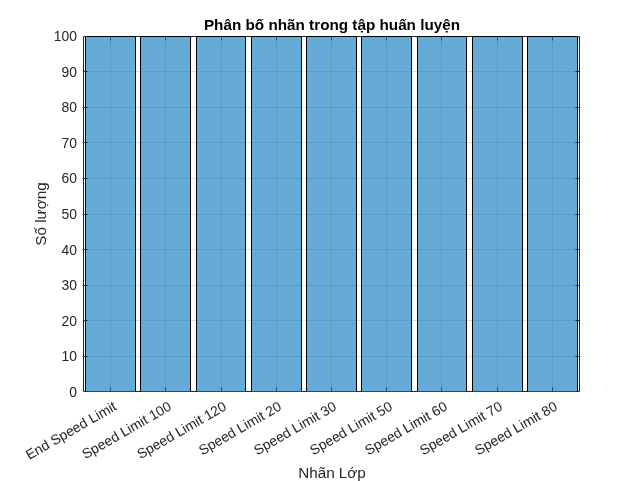

imdsSigns = imageDatastore(trainFolder, IncludeSubfolders=true, LabelSource="foldernames");
figure();
histogram(imdsSigns.Labels);
title('Phân bố nhãn trong tập huấn luyện'); 
xlabel('Nhãn Lớp');
ylabel('Số lượng');
grid on;

disp("Count Labels: ")

Count Labels: 


countlabels(imdsSigns.Labels)

ans = 9x3 table
         Label         Count    Percent
    _______________    _____    _______

    End Speed Limit     100     11.111 
    Speed Limit 100     100     11.111 
    Speed Limit 120     100     11.111 
    Speed Limit 20      100     11.111 
    Speed Limit 30      100     11.111 
    Speed Limit 50      100     11.111 
    Speed Limit 60      100     11.111 
    Speed Limit 70      100     11.111 
    Speed Limit 80      100     11.111 


Sử dụng 80% dữ liệu để huấn luyện và 20% còn lại cho tập xác thực (validation). Đảm bảo ngẫu nhiên hóa các ảnh được chọn cho tập xác thực.

[imdsTrainSigns, imdsValidSigns] = splitEachLabel(imdsSigns, 0.8, 'randomized');

disp("Số lượng ảnh trong tập huấn luyện: " + numel(imdsTrainSigns.Files));

Số lượng ảnh trong tập huấn luyện: 720


disp("Số lượng ảnh trong tập xác thực: " + numel(imdsValidSigns.Files));

Số lượng ảnh trong tập xác thực: 180


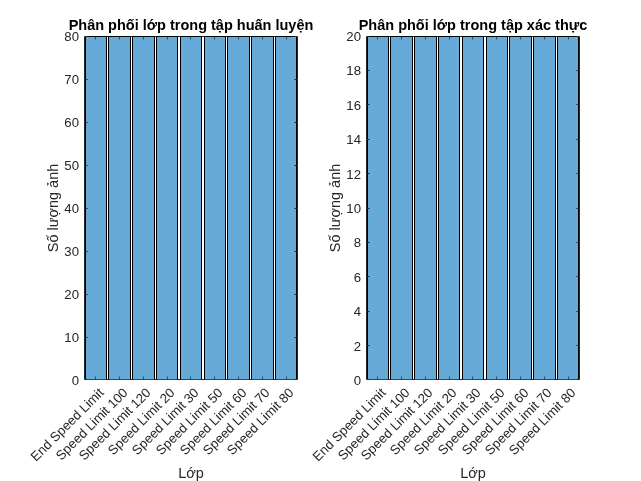

figure;
subplot(1,2,1);
histogram(imdsTrainSigns.Labels);
title('Phân phối lớp trong tập huấn luyện');
xlabel('Lớp'); ylabel('Số lượng ảnh');

subplot(1,2,2);
histogram(imdsValidSigns.Labels);
title('Phân phối lớp trong tập xác thực');
xlabel('Lớp'); ylabel('Số lượng ảnh');

## Khám phá Datastore `[1 điểm]`

Hiểu rõ dữ liệu trước khi huấn luyện là điều cần thiết.

In ra ít nhất **4 ảnh ngẫu nhiên** cho mỗi lớp (9 lớp) từ **datastore**:

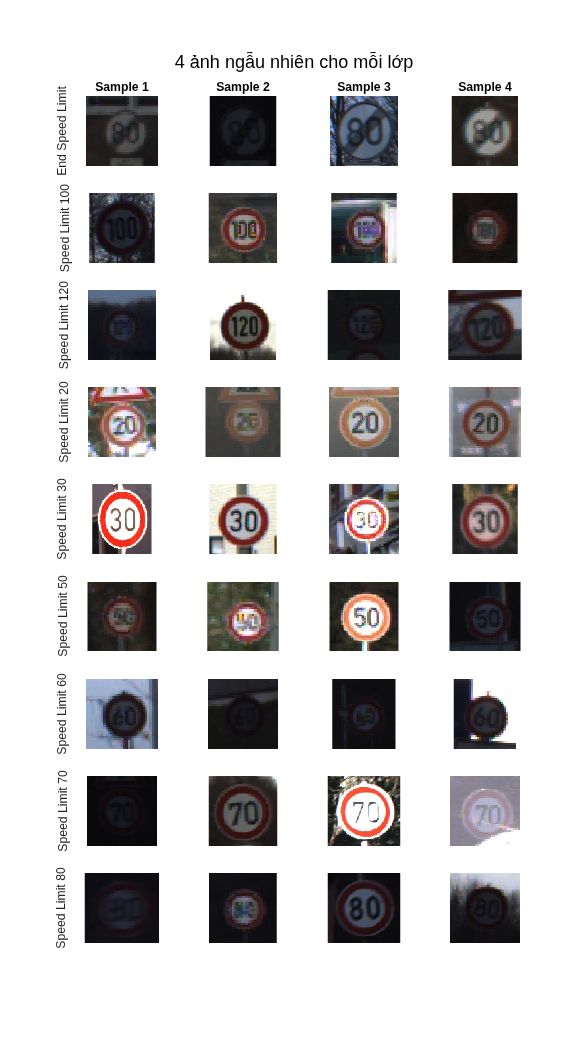

function displayRandomImagesPerClass(imds, imagesPerClass, varargin)

    % displayRandomImagesPerClass - Shows random images from each class in an image datastore
    %
    % Syntax:  

Tổng số ảnh trong datastore: 900


    %   displayRandomImagesPerClass(imds, imagesPerClass)
    %   displayRandomImagesPerClass(imds, imagesPerClass, 'ParameterName', ParameterValue, ...)

Số lượng ảnh theo từng lớp:


    %
    % Required Inputs:

         Label         Count
    _______________    _____

    End Speed Limit     100 
    Speed Limit 100     100 
    Speed Limit 120     100 
    Speed Limit 20      100 
    Speed Limit 30      100 
    Speed Limit 50      100 
    Speed Limit 60      100 
    Speed Limit 70      100 
    Speed Limit 80      100 



    %   imds - Image datastore containing labeled images
    %   imagesPerClass - Number of images to display for each class

Một số kích thước của 5 ảnh mẫu:


    %
    % Optional Name-Value Pairs:
    %   'FigurePosition' - [left bottom width height] for figure (default: [100 100 1000 1800])
    %   'MainTitle' - Title for the entire figure (default: '[imagesPerClass] ảnh ngẫu nhiên cho mỗi lớp')

Ảnh 1: 48x46x3
Ảnh 2: 64x69x3
Ảnh 3: 38x39x3
Ảnh 4: 43x42x3
Ảnh 5: 57x56x3


    %   'ImageTitleFormat' - Format for image titles (default: 'Ảnh %d')
    %   'ShowClassLabels' - Whether to show class labels (default: true)
    
    p = inputParser;
    p.addRequired('imds');
    p.addRequired('imagesPerClass', @isnumeric);
    p.addParameter('FigurePosition', [100 100 1000 1800], @(x)isnumeric(x) && length(x)==4);
    p.addParameter('MainTitle', '', @ischar);
    p.addParameter('ImageTitleFormat', 'Ảnh %d', @ischar);
    p.addParameter('ShowClassLabels', true, @islogical);
    p.parse(imds, imagesPerClass, varargin{:});
    
    figurePosition = p.Results.FigurePosition;
    imageTitleFormat = p.Results.ImageTitleFormat;
    showClassLabels = p.Results.ShowClassLabels;
    
    if isempty(p.Results.MainTitle)
        mainTitle = sprintf('%d ảnh ngẫu nhiên cho mỗi lớp', imagesPerClass);
    else
        mainTitle = p.Results.MainTitle;
    end
    
    categories = unique(imds.Labels);
    numClasses = numel(categories);
    
    figure('Position', figurePosition); 
    for i = 1:numClasses
        currentClassImages = find(imds.Labels == categories(i));
        
        if length(currentClassImages) >= imagesPerClass
            randomIndices = currentClassImages(randperm(length(currentClassImages), imagesPerClass));
            
            for j = 1:imagesPerClass
                subplot(numClasses, imagesPerClass, (i-1)*imagesPerClass + j);
                img = readimage(imds, randomIndices(j));
                imshow(img);
                
                if showClassLabels && j == 1
                    ylabel(string(categories(i)), 'Interpreter', 'none');
                end
                
                if i == 1
                    title(sprintf(imageTitleFormat, j));
                end
            end
        else
            disp("Lớp " + categories(i) + " không có đủ " + imagesPerClass + " ảnh");
        end
    end
    
    sgtitle(mainTitle);
end


- **Lưu ý:** Các ảnh nhỏ, tối, mờ hoặc khó nhìn.

- Tất cả ảnh ở định dạng **RGB**, với kích thước không đồng nhất.

- Trước khi huấn luyện, bạn cần thay đổi kích thước các ảnh này để phù hợp với lớp đầu vào của mô hình.

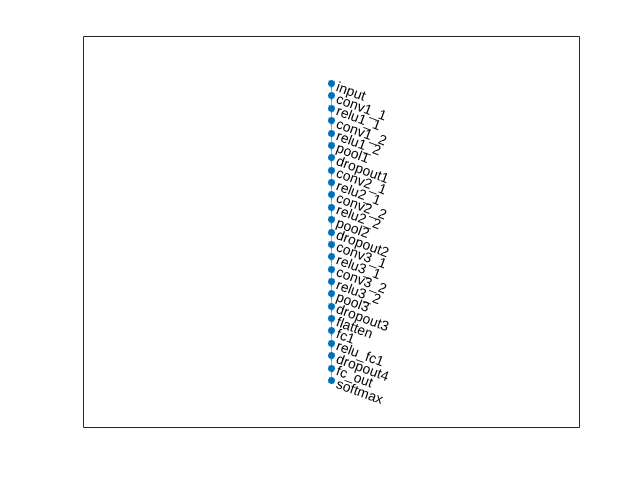

displayRandomImagesPerClass(imdsSigns, 4, ImageTitleFormat='Sample %d');

Khám phá datastore có thể cung cấp các thông tin quan trọng, như tổng số ảnh trong datastore:

totalImages = numel(imdsSigns.Files);
disp("Tổng số ảnh trong datastore: " + totalImages);

Và số lượng ảnh theo từng lớp, sử dụng hàm `countEachLabel `hoặc` countlabels`:

disp("Số lượng ảnh theo từng lớp:");
classDistribution = countEachLabel(imdsSigns);
disp(classDistribution);
numSamplesToCheck = 5;
disp("Một số kích thước của " + numSamplesToCheck + " ảnh mẫu:");
for i = 1:numSamplesToCheck
    img = readimage(imdsSigns, randi(totalImages));
    disp("Ảnh " + i + ": " + join(string(size(img)), "x"));
end

## Định nghĩa Kiến trúc Mạng `[1 điểm]`

**Thiết kế mạng thần kinh từ đầu dựa trên lựa chọn của bạn để đạt độ chính xác yêu cầu.**

Ví dụ: Mở **Deep Network Designer App** để tạo và xuất một mạng với các lớp sau:

- `imageInputLayer`

- `convolution2dLayer`

- `reluLayer`

- `maxPooling2dLayer`

- `fullyConnectedLayer`

- `softmaxLayer`

(Đảm bảo bạn chỉ định đúng **OutputSize** cho lớp `fullyConnectedLayer`)

net = dlnetwork;
tempNet = [
    % Input layer (grayscale 32x32)
    imageInputLayer([32 32 1], "Name", "input", "Normalization", "zscore")

Number of channels in augmented images: 1


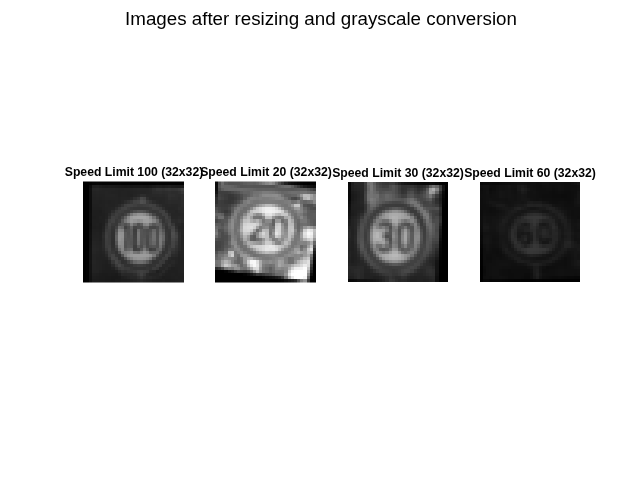

    
    % 1st convolutional block
    convolution2dLayer([3 3], 32, "Padding", "same", "Name", "conv1_1")
    reluLayer("Name", "relu1_1")
    convolution2dLayer([3 3], 32, "Name", "conv1_2")
    reluLayer("Name", "relu1_2")
    maxPooling2dLayer([2 2], "Stride", [2 2], "Name", "pool1")
    dropoutLayer(0.25, "Name", "dropout1")
    
    % 2nd convolutional block
    convolution2dLayer([3 3], 64, "Padding", "same", "Name", "conv2_1")
    reluLayer("Name", "relu2_1")
    convolution2dLayer([3 3], 64, "Name", "conv2_2")
    reluLayer("Name", "relu2_2")

    maxPooling2dLayer([2 2], "Stride", [2 2], "Name", "pool2")
    dropoutLayer(0.25, "Name", "dropout2")
    
    % 3rd convolutional block
    convolution2dLayer([3 3], 64, "Padding", "same", "Name", "conv3_1")
    reluLayer("Name", "relu3_1")
    convolution2dLayer([3 3], 64, "Name", "conv3_2")
    reluLayer("Name", "relu3_2")
    maxPooling2dLayer([2 2], "Stride", [2 2], "Name", "pool3")
    dropoutLayer(0.25, "Name", "dropout3")
    
    % Classification block
    flattenLayer("Name", "flatten")
    fullyConnectedLayer(512, "Name", "fc1")
    reluLayer("Name", "relu_fc1")
    dropoutLayer(0.5, "Name", "dropout4")
    fullyConnectedLayer(9, "Name", "fc_out")
    softmaxLayer("Name", "softmax")
    % classificationLayer("Name", "classification") % Removed classificationLayer - not compatible with dlnetwork
];

% deepNetworkDesigner(tempNet);

net = addLayers(net, tempNet);

clear tempNet;

net = initialize(net);
figure()

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
                       MaxEpochs: 555
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 125
                   MiniBatchSize: 128
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1x1 augmentedImageDatastore]
             

plot(net);

## Thay đổi Kích thước Dữ liệu Huấn luyện `[0.5 điểm]`

Thay đổi kích thước dữ liệu huấn luyện và xác thực để khớp với **InputSize** đã thiết lập ở trên (nếu cần):

augOptions = imageDataAugmenter(...

Bắt đầu huấn luyện mạng...


    'RandRotation', [-15 15], ...
    'RandXTranslation', [-2 2], ...
    'RandYTranslation', [-2 2], ...
    'RandXScale', [0.9 1.1], ...

Thời gian bắt đầu: 17-Jun-2025 08:29:42


    'RandYScale', [0.9 1.1]);

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:04        0.001                            2.1942
            1        1       00:00:06        0.001          2.1797                  
           50       10       00:00:30        0.001          1.9242            1.9379
          100       20       00:00:45        0.001          1.8453            1.8231
          150       30       00:00:59        0.001          1.5211            1.5599
          200       40       00:01:13        0.001          1.2215            1.0248
          250       50       00:01:28        0.001          0.5928           0.57367
          300       60       00:01:43        0.001         0.42563           0.20017
          350       70       00:01:57        0.001          0.2086           0.10637
          400       80       00:02:11        0.001         0.1935


augImdsTrainSigns = augmentedImageDatastore([32 32], imdsTrainSigns, ...
    'DataAugmentation', augOptions, ...

Tổng thời gian huấn luyện: 00:05:11


    'ColorPreprocessing', 'rgb2gray', ...
    'OutputSizeMode', 'resize');

augImdsValidSigns = augmentedImageDatastore([32 32], imdsValidSigns, ...
    'ColorPreprocessing', 'rgb2gray', ...
    'OutputSizeMode', 'resize');

Mô hình đã được lưu với tên: TrafficSignNet20250617.mat


Thông tin mô hình đã huấn luyện:


data = read(augImdsTrainSigns);

  25x1 Layer array with layers:

     1   'input'      Image Input       32x32x1 images with 'zscore' normalization
     2   'conv1_1'    2-D Convolution   32 3x3x1 convolutions with stride [1  1] and padding 'same'
     3   'relu1_1'    ReLU              ReLU
     4   'conv1_2'    2-D Convolution   32 3x3x32 convolutions with stride [1  1] and padding [0  0  0  0]
     5   'relu1_2'    ReLU              ReLU
     6   'pool1'      2-D Max Pooling   2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     7   'dropout1'   Dropout           25% dropout
     8   'conv2_1'    2-D Convolution   64 3x3x32 convolutions with stride [1  1] and padding 'same'
     9   'relu2_1'    ReLU              ReLU
    10   'conv2_2'    2-D Convolution   64 3x3x64 convolutions with stride [1  1] and padding [0  0  0  0]
    11   'relu2_2'    ReLU              ReLU
    12   'pool2'      2-D Max Pooling   2x2 max pooling w

img = data.input{1};
numChannels = size(img, 3);
fprintf('Number of channels in augmented images: %d\n', numChannels);
figure;
numSamplesToDisplay = 4;

testFolder = "/MATLAB Drive/German_Traffic_Sign/Test"

for i = 1:numSamplesToDisplay
    subplot(1, numSamplesToDisplay, i);

imdsValidSigns =   ImageDatastore with properties:

                       Files: {
                              ' .../German_Traffic_Sign/Test/End Speed Limit/sign00011221.png';
                              ' .../German_Traffic_Sign/Test/End Speed Limit/sign00011223.png';
                              ' .../German_Traffic_Sign/Test/End Speed Limit/sign00011224.png'
                               ... and 285 more
                              }
                     Folders: {
                              '/MATLAB Drive/German_Traffic_Sign/Test'
                              }
                      Labels: [End Speed Limit; End Speed Limit; End Speed Limit ... and 285 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @r

    
    data = read(augImdsTrainSigns);
    img = data.input{1};
    label = string(data.response(1));

scrores = 288x9 single matrix
    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


classNames = 9x1 categorical array
     End Speed Limit 
     Speed Limit 100 
     Speed Limit 120 
     Speed Limit 20 
     Speed Limit 30 
     Speed Limit 50 
     Speed Limit 60 
     Speed Limit 70 
     Speed Limit 80 


    imshow(img);

YPred = 288x1 categorical array
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 


YTest = 288x1 categorical array
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 


    title(sprintf('%s (%dx%d)', char(label), size(img,1), size(img,2)));

accuracy = 0.9965

end

Test accuracy: 99.65%


sgtitle('Images after resizing and grayscale conversion');
% disp("Input size for CNN: " + inputSize(1) + "x" + inputSize(2) + "x" + inputSize(3));

## Cài đặt các Tùy chọn Huấn luyện `[1 điểm]`

Cài đặt các tùy chọn huấn luyện:

- Đặt trình giải (solver) là `"adam"`.

- Bao gồm dữ liệu xác thực đã tách ra từ trước.

- Đặt tùy chọn `"Shuffle"` thành `"every-epoch"`.

- Đặt tùy chọn `"Plots"` thành `"training-progress"`.

- Các tùy chọn khác tùy thuộc vào hệ thống của bạn.

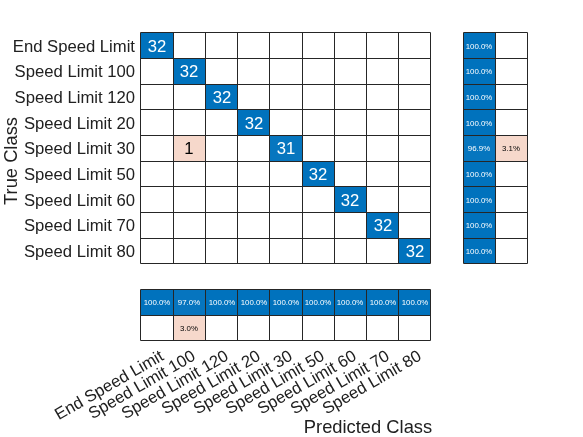

base_options = trainingOptions('adam', ...
    ValidationData=augImdsValidSigns, ...
    Shuffle='every-epoch', ...
    Plots='training-progress', ...
    MaxEpochs=555, ... % very big epochs, but don't worry, we have early stopping below.

    ValidationPatience=5, ...
    InitialLearnRate=0.001, ...
    LearnRateSchedule='piecewise', ...
    LearnRateDropFactor=0.1, ...
    LearnRateDropPeriod=125);

alt_options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 55, ...
    'MiniBatchSize', 128, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augImdsValidSigns, ...
    'ValidationFrequency', 30, ...
    'ValidationPatience', 10, ...
    'Verbose', true, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'auto');

options = base_options

## Huấn luyện Mạng `[0.5 điểm]`

Các bước cần thiết đã được thiết lâp, và đến lúc huấn luyện mạng của bạn!

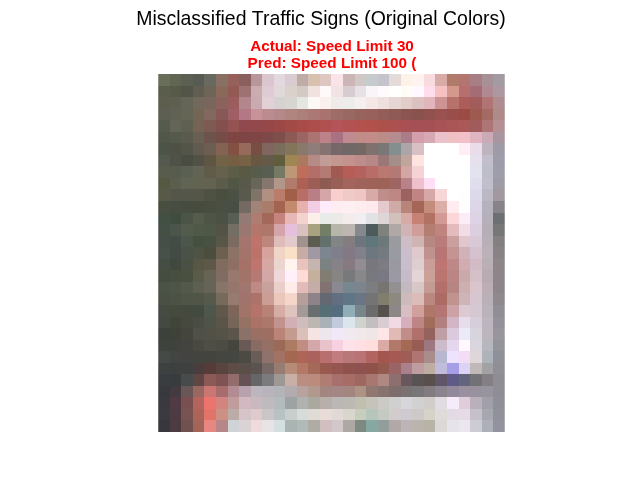

fprintf('Bắt đầu huấn luyện mạng...\n');
rng(5);

startTime = datetime('now');
fprintf('Thời gian bắt đầu: %s\n', string(startTime));
myNet = trainnet(augImdsTrainSigns, net, "crossentropy", options);
endTime = datetime('now');

trainingDuration = endTime - startTime;
fprintf('Tổng thời gian huấn luyện: %s\n', string(trainingDuration));
modelName = 'TrafficSignNet' + string(year(endTime)) + ...
            sprintf('%02d', month(endTime)) + ...
            sprintf('%02d', day(endTime)) + '.mat';
            
save(modelName, 'net', 'options', 'trainingDuration');
fprintf('Mô hình đã được lưu với tên: %s\n', modelName);
fprintf('Thông tin mô hình đã huấn luyện:\n');
disp(net.Layers);

## Hiệu suất trên Dữ liệu Kiểm tra` [1 điểm]`

Khi bạn đã huấn luyện xong mạng, hãy đánh giá hiệu suất của nó trên dữ liệu kiểm tra.

Đừng quên thay đổi kích thước các ảnh để phù hợp với kích thước đầu vào của mạng đã huấn luyện:

testFolder = "/MATLAB Drive/German_Traffic_Sign/Test"

Sử dụng dữ liệu kiểm tra để đánh giá mạng đã huấn luyện:

imdsValidSigns = imageDatastore(testFolder, IncludeSubfolders=true, LabelSource="foldernames")
augImdsTestSigns = augmentedImageDatastore([32 32], imdsValidSigns, ...
    'ColorPreprocessing', 'rgb2gray', ... 
    'OutputSizeMode', 'resize');
scrores=minibatchpredict(myNet, augImdsTestSigns)
classNames = categorical(unique(imdsSigns.Labels))
YPred = scores2label(scrores, classNames)
YTest = imdsValidSigns.Labels
accuracy = mean(YPred==YTest)
fprintf('Test accuracy: %.2f%%\n', accuracy*100);

Khám phá số lượng ảnh của từng nhãn được phân loại đúng và sai bằng cách sử dụng biểu đồ nhầm lẫn (confusion chart):

figure;
cm = confusionchart(YTest, YPred);
cm.Title = 'Confusion Matrix for Traffic Sign Classification';
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
cm.FontSize = 12;

Cuối cùng, hiển thị tất cả các ảnh bị phân loại sai:

misclassifiedIndices = find(YPred ~= YTest);
numMisclassified = length(misclassifiedIndices);

if numMisclassified > 0
    numCols = min(5, numMisclassified);
    numRows = ceil(min(20, numMisclassified) / numCols);
    
    for i = 1:min(20, numMisclassified) % Show at most 20 misclassified images
        subplot(numRows, numCols, i);
        idx = misclassifiedIndices(i);
        img = readimage(imdsValidSigns, idx); 
        imshow(img);
        
        actualLabel = string(YTest(idx));
        predictedLabel = string(YPred(idx));
        % confidence = max(allScores(idx, :)) * 100;
        
        title({sprintf('Actual: %s', actualLabel), ...
               sprintf('Pred: %s (%.1f%%)', predictedLabel)}, ...
               'Color', 'r');
    end
    sgtitle('Misclassified Traffic Signs (Original Colors)', 'FontSize', 14);
else
    text(0.5, 0.5, 'No misclassified images!', 'FontSize', 20, 'HorizontalAlignment', 'center');
end

*Copyright 2024 The MathWorks, Inc.*

*Dr. Quoc Bao Diep.*